mode='nova/'

mode = 'nova/'

fileFolder=fullfile(['receive/', mode]);
dirOutput=dir(fullfile(fileFolder,'*.txt'));
fileNames={dirOutput.name};

file_name=fileNames{end}

file_name = '20211214133154.txt'

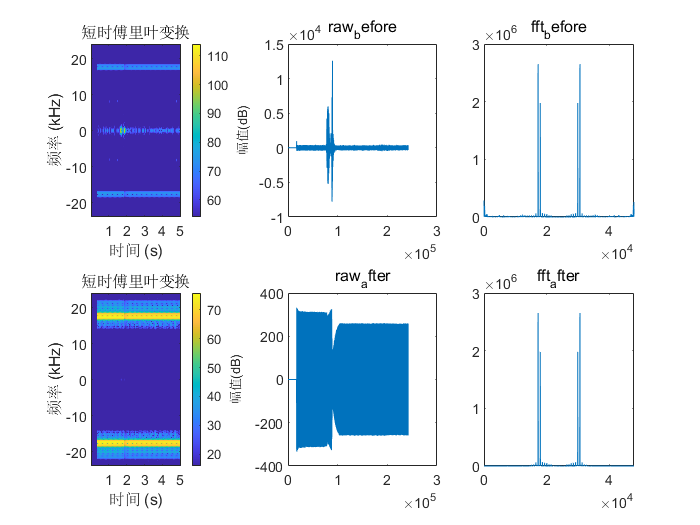

file=['receive/' , mode, file_name];
data= importdata(file);

fs=48000;
N=8;

figure;
subplot(2,3,1);
stft(data, fs, 'FFTLength',1024);
subplot(2,3,2);
plot(data);
title raw_before;
subplot(2,3,3);
plot(abs(fft(data, fs)));
title fft_before;

data=highpass(data, 16000, fs);

subplot(2,3,4);
stft(data, fs, 'FFTLength',1024);
subplot(2,3,5);
plot(data);
title raw_after;
subplot(2,3,6);
plot(abs(fft(data, fs)));
title fft_after;



llap(data, file_name, mode, N);

time = 241920

total_phase =     9.3532   14.8419    2.1745   -7.2834    1.8652   -1.4790    0.1347  120.4058


ans = 19.6922

total_dist =     1.4059    2.2309    0.3268   -1.0948    0.2804   -0.2223    0.0202   18.0986


ans = 2.9600

function [tot_phase, tot_dist]= Ndist(power_phase)

dist =[];
speed = [];
tot_phase=0.0;
chphase_list=[];
for i=2:length(power_phase)
    lastphase = power_phase(i-1);
    if abs(power_phase(i) - lastphase) > pi
        if lastphase <0
            chphase = 2*pi - power_phase(i) + lastphase; 
        else 
            chphase = 2*pi + power_phase(i) - lastphase;
        end
    else
        chphase = power_phase(i) -lastphase;
    end
    chphase_list=[chphase_list chphase];
    tot_phase = tot_phase +chphase;
    dist(i)= (chphase/(2*pi)) * (34000/18000);
    speed(i)= dist(i)*48000/8;
end

tot_dist=sum(dist)/2;

end


function [data, file_name, mode, N] = llap(data, file_name, mode, N)
fs = 48000;
f = [];
f0 = 17300;
reduce=680;
gap=700;



time = length(data)
for i=1:N
    f = [f f0+(i-1)*gap];
end

t = 0:1/fs:(time-1)/fs;
I = [];
Q = [];

% raw fre
for i=1:N
  
    I = [I; cos(2*pi*f(i)*t)];
    Q = [Q; cos(2*pi*f(i)*t+pi/2)];
%     Q = [Q; -sin(2*pi*f(i)*t)];
end

% IQ
I1=data .* I';
Q1=data .* Q';

% figure;
% for i=1:N   
%     plot(abs(fft(I1(:, i)', fs)));
% end
% title zhengjiao;

if mod(time, 16)~=0
    I1=I1(1:time-mod(time, 16), :)
    Q1=Q1(1:time-mod(time, 16), :)
end




%cic
filter=dsp.CICDecimator(16,17,3);
I1_cic = [];
Q1_cic = [];
for i=1:N
    I1_cic =[I1_cic; filter(I1(:, i))'];
    Q1_cic =[Q1_cic; filter(Q1(:, i))'];
end




% windowSize=200;
% stepSize=100;
% 
% b = (1/windowSize)*ones(windowSize, 1);
% a = 1;
% 
% windowEnd = windowSize:stepSize:time-windowSize+1;
%  
% I1_cic = [];
% Q1_cic = [];
% for i=1:N
%     temp_I=filter(b, a, I1(:, i))';
%     temp_Q=filter(b, a, Q1(:, i))';
%     
%     I1_cic =[I1_cic; temp_I(windowEnd)];
%     Q1_cic =[Q1_cic; temp_Q(windowEnd)];
%     I1_cic =[I1_cic; temp_I];
%     Q1_cic =[Q1_cic; temp_Q];
%     
%     
% 
% end 
% 



% padding
% if size(I1_cic, 2)>reduce
%     I1_cic=I1_cic(:, 1:reduce);
% else
%     I1_cic = padarray(I1_cic, [0 (reduce-size(I1_cic, 2))/2]);
% end
% 
% if size(Q1_cic, 2)>reduce
%     Q1_cic=Q1_cic(:, 1:reduce);
% else
%     Q1_cic = padarray(Q1_cic, [0 (reduce-size(Q1_cic, 2))/2]);
% end


I1_normal=normalize(I1_cic, 2);
Q1_normal=normalize(Q1_cic, 2);


power_am=sqrt(I1_normal.^2+Q1_normal.^2);
power_phase= atan2(I1_normal, Q1_normal);

% for i =1:N
%     figure;
%     plot(power_am);
%     title "am"+i;
% 
%     figure;
%     plot(power_phase);
%     title "phase"+i;
% end
total_phase=[];
total_dist=[];
for i = 1:N
    [temp_phase, temp_dist] = Ndist(power_phase(i, :));
    total_phase =[total_phase  temp_phase];
    total_dist = [total_dist  temp_dist];
end
total_phase
mean(abs(total_phase))
total_dist
mean(abs(total_dist))

end





